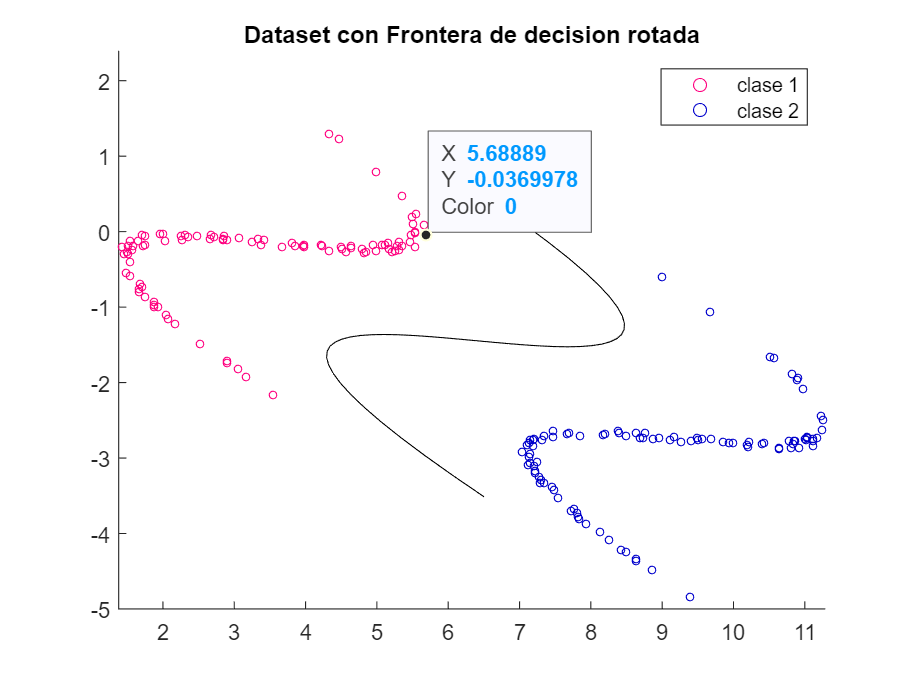

%load('Entrenamiento.mat');
%data = train2clases_relacion_1a4;
data = test2clases_lejos;
figure
hold on
ele = 12;
colormap([1 0 .5; % magenta
           1 .5 0; % anaranjado
           0 .6 0; % verde 
           0 0 .8]); % azul
datosclase1 = scatter(data(data(:,3)==0,1), data(data(:,3)==0,2),ele, data(data(:,3)==0,3));
datosclase2 = scatter(data(data(:,3)==1,1), data(data(:,3)==1,2),ele, data(data(:,3)==1,3));
plot (Frontera_2clases(:,1),Frontera_2clases(:,2),'k')
title('Dataset con Frontera de decision rotada')
legend([datosclase1,datosclase2],{'clase 1','clase 2'})
hold off

xlim([2.00 11.00])
ylim([-5.00 2.00])
ax = gca;
chart = ax.Children(3);
datatip(chart,6.441,0.06641);

xlim([1.38 11.28])
ylim([-5.00 2.39])

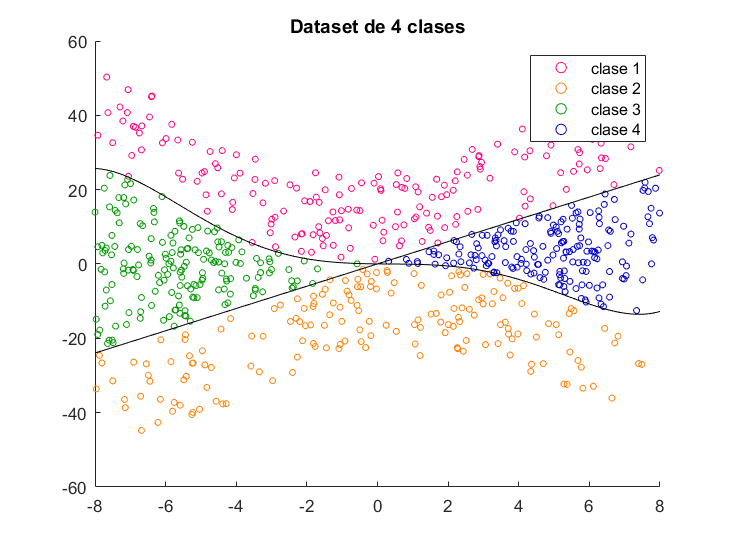


%load('Entrenamiento.mat');
data = train4clases_700muestras;

figure
hold on
ele = 12;
colormap([1 0 .5; % magenta
           1 .5 0; % anaranjado
           0 .6 0; % verde 
           0 0 .8]); % azul
datosclase1 = scatter(data(data(:,3)==0,1), data(data(:,3)==0,2),ele, data(data(:,3)==0,3));
datosclase2 = scatter(data(data(:,3)==1,1), data(data(:,3)==1,2),ele, data(data(:,3)==1,3));
datosclase3 = scatter(data(data(:,3)==2,1), data(data(:,3)==2,2),ele, data(data(:,3)==2,3));
datosclase4 = scatter(data(data(:,3)==3,1), data(data(:,3)==3,2),ele, data(data(:,3)==3,3));
plot (Frontera1_clase4(:,1),Frontera1_clase4(:,2),'k')
plot (Frontera2_clase4(:,1),Frontera2_clase4(:,2),'k')
legend([datosclase1,datosclase2,datosclase3,datosclase4],{'clase 1','clase 2','clase 3','clase 4'})
title('Dataset de 4 clases')
hold off